# Applying PCA

In this live script you'll use the `pca` function to perform [Principle Component Analysis](https://www.mathworks.com/help/stats/principal-component-analysis-pca.html) and use the results to explore the human activity dataset [included with MATLAB](https://www.mathworks.com/help/stats/sample-data-sets.html).

## Introduction

You've already learned how principle component analysis can help simplify and improve predictive models by reducing the dimensionality of a dataset. PCA is also a powerful tool for data analysis and visualization, particularly when working with wide (i.e. many variable) datasets. Understanding these datasets can be very challenging as it's difficult to inspect, summarize, and visualize variables, let alone look for potential relationships between them. By focusing your analysis on high-variance principle component features instead, you can often capture the most important aspects of your data in a relatively small number of features.

### Load the data

The human activity dataset contains observations of human activity measured via cell phone accelerometers. The dataset contains 60 features that were extracted from the accelerometer signals, as well as labels describing the corresponding activity being performed. The meaning of each feature and the specifics of the feature extraction from the raw signals are beyond the scope of this reading, however, you will learn several techniques for extracting features from signals in an upcoming module. Run the code below to load the human activity dataset and display the description:

load humanactivity
disp(Description)

    "                        === Human Activity Data ===                        "
    "                                                                           "
    " The humanactivity data set contains 24,075 observations of five different "
    " physical human activities: Sitting, Standing, Walking, Running, and       "
    " Dancing. Each observation has 60 features extracted from acceleration     "
    " data measured by smartphone accelerometer sensors. The data set contains  "
    " the following variables:                                                  "
    "                                                                           "
    " * actid — Response vector containing the activity IDs in integers: 1, 2, "
    " 3, 4, and 5 representing Sitting, Standing, Walking, Running, and         "
    " Dancing, respectively                                                     "
    " * actnames — Activity names corresponding to the integer activity IDs    "
    " * feat — Fea

### Create a table and inspect the data

Run the code below to load the data into a `table`. The data consists of 60 continuous features (the activity labels are not used in this script). You can then examine them using the interactive table output to explore the dataset. 

tbl = array2table(feat,'VariableNames',featlabels)

tbl = 24075×60 table
    TotalAccXMean    TotalAccYMean    TotalAccZMean    BodyAccXRMS    BodyAccYRMS    BodyAccZRMS    BodyAccXCovZeroValue    BodyAccXCovFirstPos    BodyAccXCovFirstValue    BodyAccYCovZeroValue    BodyAccYCovFirstPos    BodyAccYCovFirstValue    BodyAccZCovZeroValue    BodyAccZCovFirstPos    BodyAccZCovFirstValue    BodyAccXSpectPos1    BodyAccXSpectPos2    BodyAccXSpectPos3    BodyAccXSpectPos4    BodyAccXSpectPos5    BodyAccXSpectPos6    BodyAccXSpectVal1    BodyAccXSpectVal2    BodyAccXSpectVal3    BodyAccXSpectVal4    BodyAccXSpectVal5

When exploring a dataset with 60 features, it's difficult to get a firm understanding of each individual feature. However, it should be clear that the features are all continuous (i.e. not discrete) and possess different scales.

## Principle Component Analysis

In the next few sections you will learn how to compute the principle components, scores, and variances of the continuous variables in your dataset.

### Prepare the dataset for PCA

Run the code in this section to prepare the activity data for PCA.

- PCA should only be applied to continuous features. To perform PCA in MATLAB, it is also necessary to organize the continuous features into a matrix. In this example, all 60 of the original features are continuous, but this will not be the case in general. The code below extracts the features from the `table` into a `double` matrix.

X = tbl{:,:};

- When performing PCA, the features should also have 0 mean and possess similar scales. The code below scales and mean-centers the features in each column of `X` using the transformation: $X^i\to \frac{X^i-E[X^i]}{Max[X^i]-Min[X^i]}$, where $X^i$ is the $i$th column (feature). All features will then have a mean of 0 and values in the range $[-0.5,0.5]$.

mu = mean(X); % Row vector of column (feature) means
r = range(X); % Row vector of column ranges
X = (X-mu)./r; % Scaled feature matrix

### Compute the principle components, scores, and variances

The code in this section computes the principle components, scores, and variances of an input data matrix using the [`pca`](https://www.mathworks.com/help/stats/pca.html) function. 

For an $m\times n$ matrix `X` - i.e. there are $m$ observations and $n$ continuous features - the outputs of the command `[P,S,V] = pca(X)` are as follows:

- `P`: An $n\times n$ matrix of principle components where each column of `C` is a principle component*. The components are ordered by decreasing variance so that P`(:,1)` contains the first principle component (most variance), and P`(:,end)` contains the last principle component (least variance).

- `S`: An $m\times n$ matrix of scores. Each column in `S `corresponds to a component in P, so `S(:,1)` contains the scores for the first principle component, and `S(:,end)` contains the scores for the last principle component.

- `V`: An $n\times 1$vector of variances corresponding to the components in P, so V`(1)` contains the variance along the direction of the first principle component and V`(end)` is the data variance along the direction of the last principle component. These are also the variances of the component scores, so `V(1)` is equal to `var(S(:,1))` and `V(end)` is equal to `var(S(:,end))`.

[P,S,V] = pca(X)

P =     0.1047   -0.1549   -0.1919   -0.2086   -0.0504   -0.1932    0.0071    0.6264    0.1687    0.2236    0.1992    0.1151    0.4634    0.2900   -0.0878   -0.0469    0.0198    0.0364   -0.0050   -0.0244    0.0331   -0.0112   -0.0372   -0.0175    0.0204    0.0162   -0.0093   -0.0137    0.0161    0.0144    0.0055    0.0118   -0.0028    0.0051    0.0032    0.0267    0.0179    0.0089   -0.0217    0.0047    0.0084    0.0206   -0.0250    0.0126    0.0024   -0.0058    0.0075   -0.0108   -0.0067   -0.0179
   -0.0959   -0.1874    0.4877    0.6623   -0.3764    0.1281   -0.2060    0.1806    0.1216   -0.0239   -0.0011    0.0286    0.1553    0.0485    0.0130   -0.0267   -0.0116    0.0224    0.0005    0.0039    0.0070   -0.0100   -0.0120   -0.0094    0.0142    0.0110    0.0007   -0.0015    0.0001    0.0116   -0.0006   -0.0039   -0.0080    0.0050    0.0076   -0.0009   -0.0077    0.0012   -0.0039   -0.0055   -0.0015   -0.0085    0.0034    0.0007    0.0096    0.0083    0.0080    0.0014   -0.0016   -0

S =     0.8800   -0.0714    0.1641   -0.2322   -0.1993   -0.1334   -0.0149    0.4159    0.0584    0.0131    0.1531    0.1000    0.1531    0.0402    0.0580    0.0094    0.0022    0.0173    0.0197   -0.0201    0.0050    0.0094   -0.0231   -0.0142    0.0046    0.0026   -0.0180    0.0038   -0.0079    0.0165    0.0151   -0.0056   -0.0166    0.0055   -0.0032    0.0129   -0.0277    0.0205   -0.0123    0.0028   -0.0026   -0.0123    0.0086   -0.0037    0.0073   -0.0028    0.0042    0.0074    0.0030    0.0052
    0.9668   -0.1820    0.0972   -0.1338   -0.2100   -0.1985    0.1161    0.3648    0.0649    0.0383    0.1750    0.1130    0.1268    0.0153   -0.0157   -0.0290   -0.0243    0.0132   -0.0029    0.0256    0.0041   -0.0187   -0.0228   -0.0098   -0.0193    0.0285   -0.0148   -0.0031    0.0073    0.0045   -0.0379    0.0029   -0.0101    0.0002   -0.0017   -0.0028   -0.0114    0.0133   -0.0060   -0.0068   -0.0013   -0.0073    0.0100   -0.0036    0.0073   -0.0019    0.0024    0.0065    0.0028    0

V =     0.6046
    0.1001
    0.0905
    0.0560
    0.0470
    0.0405
    0.0291
    0.0233
    0.0210
    0.0199


***Notes on principle components**: 

- The components specify a direction in $n$-dimensional space, where $n$ is the number of features. If you are familiar with linear algebra and/or vectors, you might recall that there are many (an infinite number, if fact) of vectors that specify the same direction but have different lengths. The particular components $\mathbf{p}^i$ returned by MATLAB as the columns of `P` have been scaled so that they have a unit length (as computed by the usual Euclidean vector norm $\Vert \mathbf{p}^i \Vert= \sqrt{\mathbf{p}^i \cdot \mathbf{p}^i }$ ). 

- The principle component directions are also non-unique, as a vector rotated through the origin by 180 degrees still lies along the same axis in $n$-dimensional space. Therefore $-\mathbf{p}^i$ can also be used as a principle component, though only one of $\{\mathbf{p}^i ,-\mathbf{p}^i \}$ is returned by MATLAB and is used in practice.

### Examine the principle component variances

Run the code in this section to plot the proportion of variance explained by each principle component feature and the cumulative variance up to and including each feature.

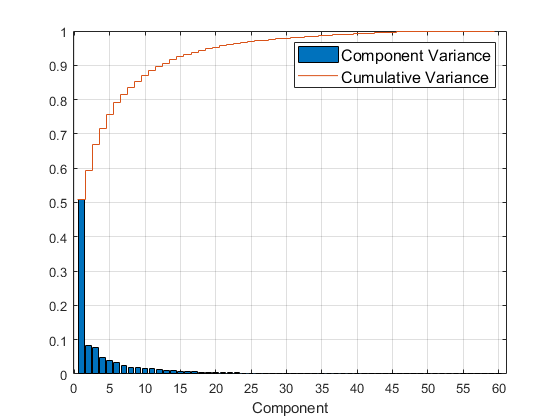

Vnorm = V/sum(V); % Normalize the variance so the total is 1
figure; hold on;
bar(Vnorm);
stairs(0.5:59.5,cumsum(Vnorm));
grid on; box on; hold off;
set(gca,'XTick',0:5:60)
legend({'Component Variance','Cumulative Variance'},'FontSize',12)
xlabel('Component')

Note that **half** of the total variance is captured by the first component feature alone, and 2/3 of the total variance is captured by the first 3! 

### Examine the original feature variances

Run the code below to calculate, sort, and plot the variances of the original (scaled) features for comparison. Note that the visual is popped out of the Live Script and maximized for easier viewing.

VOrigNorm = var(X);
[VOrigNorm,idx] = sort(VOrigNorm,'descend');
VOrigNorm = VOrigNorm/sum(VOrigNorm); % Normalize the variance so the total is 1
figure; hold on;
bar(VOrigNorm);
stairs(0.5:59.5,cumsum(VOrigNorm));
grid on; box on; hold off;
set(gca,'XTick',0.5:59.5,'XTickLabel',tbl.Properties.VariableNames(idx),'XTickLabelRotation',45)
set(gcf,'units','normalized','OuterPosition',[0 0 1 1])
legend({'Feature Variance','Cumulative Variance'},'FontSize',12,'Location','east')
xlabel('Feature')
ylim([0,1])

Clearly, variance is distributed much more evenly among the original features. For example, how many of the original features would you need to capture the same amount of variance as the first principle component? The first 3 components? 

### Relating the principle components to the original variables

While entire analyses can be completed and predictive models trained and validated using only the principle component features, it's helpful to understand how the components relate to the original features when trying to interpret the results of these analyses and models. The amount that the $i$th feature $X^i$ contributes to the $j$th principle component $P^j$ is determined by $|P_i^j|$. The sign of $P^j_i$ determines the orientation of the relationship between the component and variable. Positive implies that as the value of $X^i$ increases the value of $P^j$ increases. The opposite is true for negative values of $P^j_i$. In terms of the principle component matrix, `P`, returned by `pca`, this is given by `P(i,j)`. 

While this information can be relayed by displaying the component matrix `P`, for wide datasets additional visual aids can be very helpful. For example, the code below uses a heat map to visualize the relationships between the components and features. Rectangles with very light or dark colors indicate a larger contribution by a given feature (row) to a given component (column). Lighter shades indicate positive relationships, darker shades indicate negative relationships. Run the code below to create the heatmap. Note that the visual is popped-out of the Live Script and maximized for easier viewing.

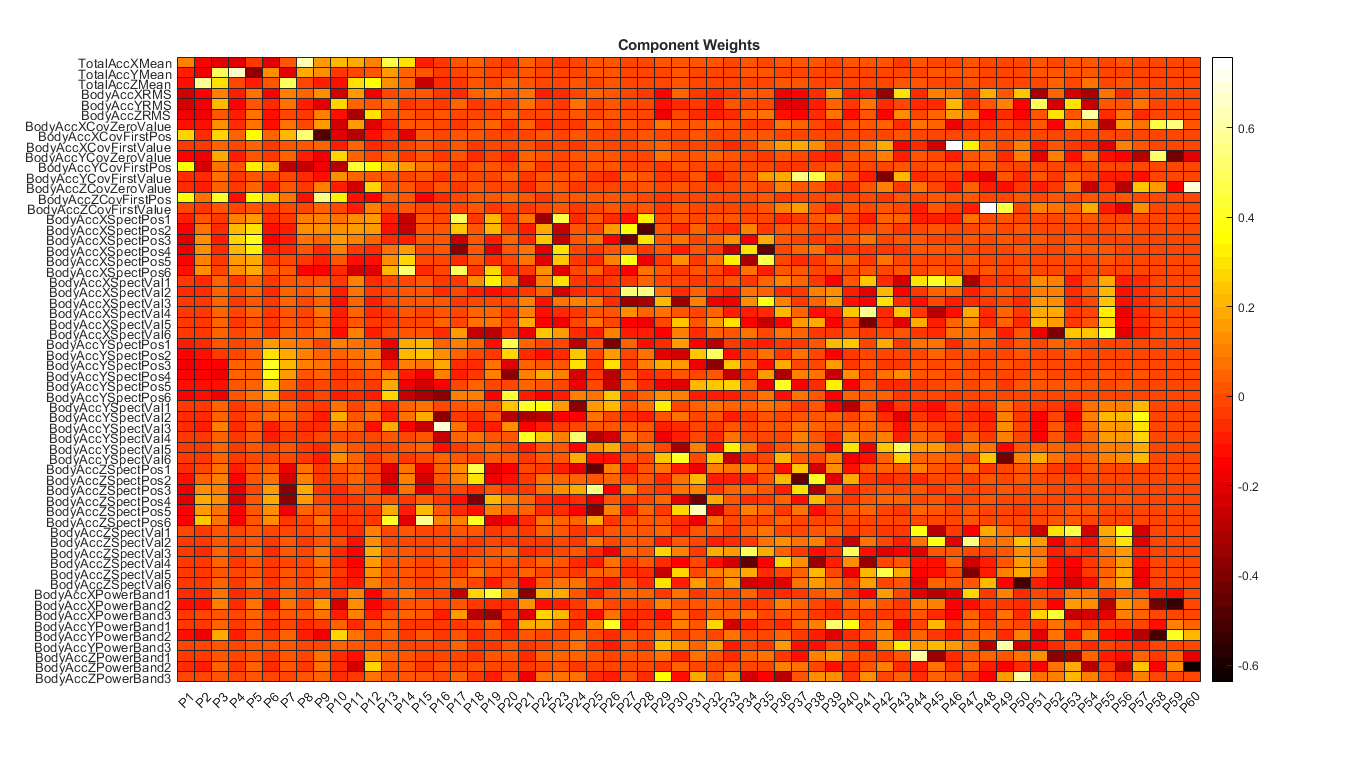

figure;
heatmap(P,'XDisplayLabels',"P"+(1:60),'YDisplayLabels',tbl.Properties.VariableNames,'Title','Component Weights','Colormap',hot(50));
set(gcf,'units','normalized','outerposition',[0 0 1 1])

Comparing this figure to the previous one, it's clear that the features with the largest (scaled) variances are also some of the biggest contributors to the first few principle components.

### Visualizing the components features

Since 2/3 of the total variance is captured by the first three components, a scatter plot of these features will provide a good deal of insight into the data structure. Run the code below to create the scatter plot, then use the Rotate and Zoom controls to explore the data structure. You can view a particular axes pair (e.g. $P^1$-$P^2$) by selecting the Rotate control, right-clicking the plot, and selecting the desired view (e.g. 'X-Y').

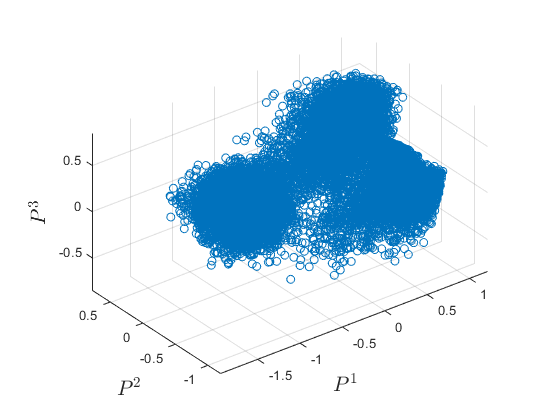

figure;
scatter3(S(:,1),S(:,2),S(:,3))
xlabel('$P^1$','FontSize',16,'Interpreter','latex')
ylabel('$P^2$','FontSize',16,'Interpreter','latex')
zlabel('$P^3$','FontSize',16,'Interpreter','latex')
axis equal;

The first three component values seem to be organized into separate clusters. Using the Rotate and Zoom controls, how many can you identify? 

### Clustering the component features

The first three component scores appear to be grouped into 6 clusters. As the cluster distribution is fairly complex, including the information from additional component features (beyond the first three) can help separate the clusters. Since the clusters are ellipsoidal  with some overlap along the boundaries, at least in the first 3 component dimensions, a Gaussian mixture model is an appropriate choice. Run the code below to fit a GMM with six clusters. The first 7 principle component features are used, which account for 80% of the total variance. The maximum number for clustering iterations are also increased to allow for slower convergence due to the complex data structure.

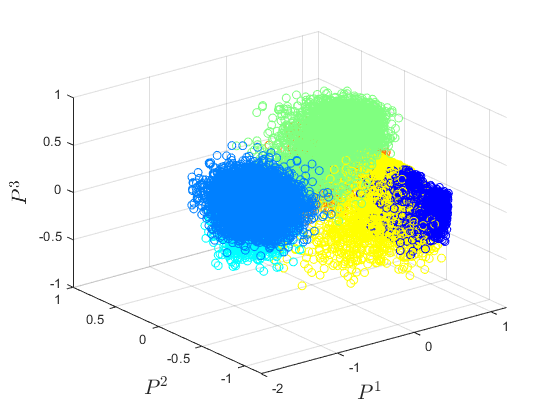

k = 6; % Number of clusters
components = 7; % Number of components features to use in clustering
opts = statset('MaxIter',500); 
gmm = fitgmdist(S(:,1:components),k,'Options',opts,'Replicates',10,'Start','randSample');
clst = cluster(gmm,S(:,1:components));
clr = jet(k);
figure; 
scatter3(S(:,1),S(:,2),S(:,3),[],clr(clst,:))
xlabel('$P^1$','FontSize',16,'Interpreter','latex')
ylabel('$P^2$','FontSize',16,'Interpreter','latex')
zlabel('$P^3$','FontSize',16,'Interpreter','latex')

### Using clusters to explore the original features

While PCA was helpful in identifying the clusters, interpreting them is difficult because each component combines information from multiple original features. However, the potential reasons behind the observed clustering can be investigated by examining the clusters like these in terms of your original features, which also allows you to utilize your domain knowledge to interpret the results. Note that, even though the clusters were identified and assigned using principle component features, each observation (row) of the original feature set corresponds to the same observation (row) of the principle component feature set, so the cluster assignments also apply to the original data. Run the code below to add the cluster assignments to the original `table`.

tbl.Cluster = clst;

You can now learn more about the original features by computing summary statistics by cluster and visualizing the distribution of values by cluster using histograms. Select a feature to summarize the original feature using the `groupsummary` function. How do the feature values differ by cluster?

feat = "BodyAccXCovFirstValue";
groupsummary(tbl,'Cluster',{'mean','median','max','min','range','std','var'},feat)

ans = 6×9 table
    Cluster    GroupCount    mean_BodyAccXCovFirstValue    median_BodyAccXCovFirstValue    max_BodyAccXCovFirstValue    min_BodyAccXCovFirstValue    range_BodyAccXCovFirstValue    std_BodyAccXCovFirstValue    var_BodyAccXCovFirstValue
    _______    __________    __________________________    ____________________________    _________________________    _________________________    ___________________________    _________________________    _________________________

       1          2570               0.0097308                      0.0095082                       0.021391                   0.00050969                      0.020882                     0.0041067          

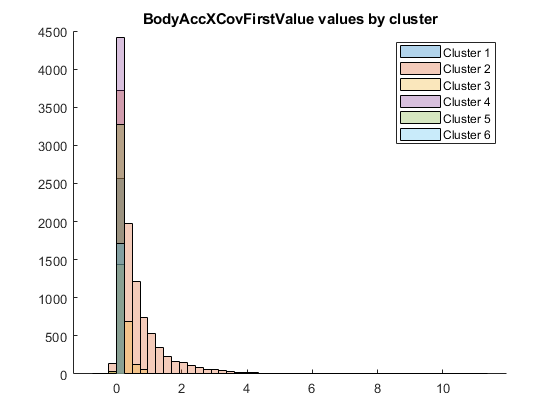

figure; hold on;
for i = 1:k
    histogram(tbl.(feat)(tbl.Cluster == i),50,'BinLimits',[min(tbl.(feat)),max(tbl.(feat))],'FaceAlpha',0.3)
end
legend("Cluster " + (1:6))
title(feat + " values by cluster")
hold off;

Alternatively, the visualization below uses a heatmap to display the results of a group calculation single statistic on the scaled* features. You can use it to quickly compare how the values of each feature differs by cluster for the chosen statistic.

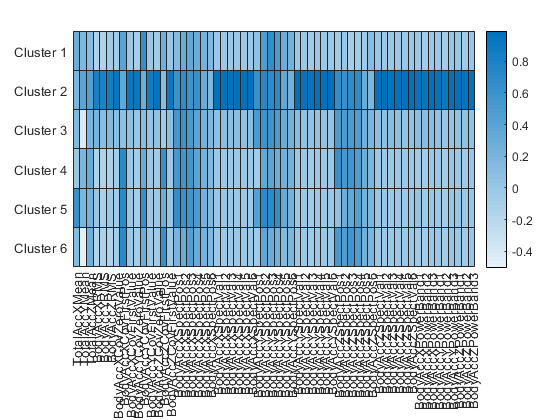

stat = "max";
data = groupsummary(X,clst,stat);
heatmap(tbl.Properties.VariableNames(1:end-1),"Cluster "+(1:6),data);

*The scaled features are used instead of the original features because features with large scales would otherwise dominate the visual. 

## Converting features to scores

While each observation (row) in the component feature set maps directly to the corresponding observation (row) in the original feature set, the same is not true for the features themselves (columns). Therefore, it is necessary to convert between the two. 

Let:

- $X$ is an $m\times n$ data matrix with features in columns and observations in rows.

- $C$ is an $n\times n$ matrix of principle components, with components in columns.

- $S$ is an $m\times n$ matrix of scores, with component features in columns and observations in rows.

The scores are obtained by projecting the data values onto the component axes. If you are familiar with matrix multiplication, this corresponds to multiplying the data matrix $X$ and component matrix $P$ so that $S = XP$. In MATLAB, this is done using the command:

While this conversion is not usually necessary at first (since `pca` function provides scores as an output), you will have to convert any* new data* to scores before using it with a supervised or unsupervised learning model trained on the principle component features. Additionally:

- If you also used PCA for dimensionality reduction and have discarded low-variance components, you should also only include scores for the components you retained.

- If your original features were mean-centered and scaled, you must also mean-center and scale new data. In particular, you should us the *original* data means and scales. 

For example, if your original feature means and scales are stored in the row vectors `mu` and `r`, your new data is stored in the matrix `Xnew,` and the number of component features used in the model is stored in `components`, the new data scores can be computed using the code below:

## Converting scores to features

If you identify values in the principle component coordinates that you would like to investigate further using the original feature values, you can also recover the original feature values from the principle components and scores applying the inverse transformation, $X = SC^T$, followed by reversing the scaling and mean centering you applied before PCA. In MATLAB, this can be done with the commands:

For example, run the code below to convert the cluster centroids found using 7 components from their principle component coordinates to the corresponding feature values. Note that If you are only working with a subset of components (scores), then `P` should be replaced with `P(:,1:components)`.

Sclst = gmm.mu; % 6 (cluster) x 7 (component) centroid locations
Xclst = Sclst*P(:,1:components)'; % Convert to original feature coordinates
Xclst = Xclst.*r+mu; % Undo scaling and mean centering
tblClst = array2table([(1:6)',Xclst],'VariableNames',['Cluster',tbl.Properties.VariableNames(1:end-1)])

tblClst = 6×61 table
    Cluster    TotalAccXMean    TotalAccYMean    TotalAccZMean    BodyAccXRMS    BodyAccYRMS    BodyAccZRMS    BodyAccXCovZeroValue    BodyAccXCovFirstPos    BodyAccXCovFirstValue    BodyAccYCovZeroValue    BodyAccYCovFirstPos    BodyAccYCovFirstValue    BodyAccZCovZeroValue    BodyAccZCovFirstPos    BodyAccZCovFirstValue    BodyAccXSpectPos1    BodyAccXSpectPos2    BodyAccXSpectPos3    BodyAccXSpectPos4    BodyAccXSpectPos5    BodyAccXSpectPos6    BodyAccXSpectVal1    BodyAccXSpectVal2    BodyAccXSpectVal3    BodyAccXSpectVal4    